clear
close all

% Flavio use exponential as an initial example
% We can switch to any distribution later.
f = @(x) exp(-x);
variance=1;
composition = 1;
q=1;
sen=1;
% similarly, let's first sample the distribution
xmax = 10; % range of samples
step_size = 0.25; % bin size
x_grid=0:step_size:xmax-step_size;
N=length(x_grid)

N = 40

ps=f(x_grid)

ps =     1.0000    0.7788    0.6065    0.4724    0.3679    0.2865    0.2231    0.1738    0.1353    0.1054    0.0821    0.0639    0.0498    0.0388    0.0302    0.0235    0.0183    0.0143    0.0111    0.0087    0.0067    0.0052    0.0041    0.0032    0.0025    0.0019    0.0015    0.0012    0.0009    0.0007    0.0006    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001


% Now, let's perform integration to obtain the c.f.
T = pi/step_size; % the period should be 2T/delta, since c.f. is symmetric, we only care half of it.
T_length=2^10;
T_step_size=2*T/T_length;
t_grid = -T:T_step_size:T-T_step_size;

% this is the c.f. by discrete integration

a = 0.5;

cfChebfun = @(t)sum(chebfun(@(x) f(x).*exp(x.*(a+1i*t)),[min(x_grid),max(x_grid)])).^composition;
cfDiscrete= @(t) sum(ps.*exp(x_grid.*(1i*t))*step_size).^composition;

cfTiltChebfun = @(t) sum(chebfun(@(x) f(x).*exp(x*(a+1i*t)),[0,xmax]))^composition;
cfTiltDiscrete = @(t) sum(ps.*exp(x_grid.*(a+1i*t))*step_size)^composition;

s=4;
[moment, cumulant, lambda, rho]=cumulants_generatorDiscrete(ps,x_grid,s);
cfTiltEdgeworth = @(t) edgeworth_CharFn(a,t,s,lambda,composition);

% let's try to use FFT, and shift it to the center.
pTilt=ps.*exp(a*x_grid);
pTilt_padding=[pTilt,zeros([1,T_length-length(pTilt)])];
pFFT = conj(fft(pTilt_padding));
cfTiltFFT_array = fftshift(pFFT)*step_size;


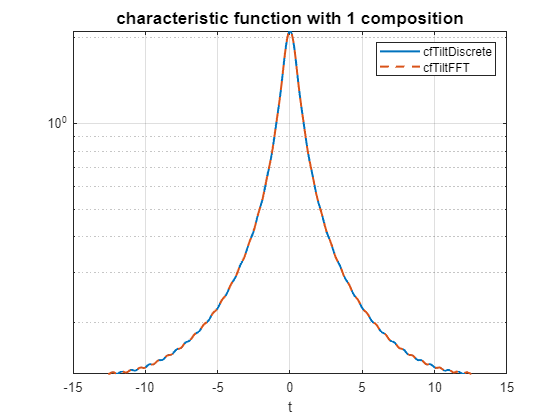

% let's take a look
figure

% cfChebfun_array = arrayfun(cfChebfun,t_grid);
% semilogy(t_grid, abs(cfChebfun_array),'-',"LineWidth",1.5,"DisplayName","cfChebfun");
% hold on

% cfDiscrete_array = arrayfun(cfDiscrete,t_grid);
% semilogy(t_grid, abs(cfDiscrete_array),'-',"LineWidth",1.5,"DisplayName","cfDiscrete");
% hold on

% cfTiltChebfun_array = arrayfun(cfTiltChebfun,t_grid);
% semilogy(t_grid, abs(cfTiltChebfun_array),'-',"LineWidth",1.5,"DisplayName","cfTiltChebfun");
% hold on

cfTiltDiscrete_array = arrayfun(cfTiltDiscrete, t_grid);
semilogy(t_grid, abs(cfTiltDiscrete_array),'-',"LineWidth",1.5,"DisplayName","cfTiltDiscrete")
hold on

% cfTiltEdgeworth_array = arrayfun(cfTiltEdgeworth,t_grid);
% semilogy(t_grid, abs(cfTiltEdgeworth_array),"LineWidth",1.5,"DisplayName","cfTiltEdgeworth")
% hold on

semilogy(t_grid, abs(cfTiltFFT_array),'--',"LineWidth",1.5,"DisplayName","cfTiltFFT")
xlabel("t");
title(sprintf("characteristic function with %d composition",composition),"FontSize",13);
legend
grid on


filterTiltChebfun = @(eps,t) sum(chebfun(@(x) max(0,1-exp(eps-x)).*exp(x*(-a+1i*t)),[eps,3*xmax]));
k_grid=0:3; % let's use 20 folds on each sides
filterTiltChebfunFolded = @(eps,t) sum(arrayfun(@(k) filterTiltChebfun(eps,t+k*2*T),k_grid));

% Alternatively, via Mathematica, we have the expression of FoldedFilter 

% BetaTermA = @(a,t) betainc(real(exp(-2*1i*pi*eps/xStep)),real(1-1i*(1+a-1i*t)*xStep/2/pi),0)*beta(real(1-1i*(1+a-1i*t)*xStep/2/pi),0);
% BetaTermB = @(a,t) betainc(real(exp(-2*1i*pi*eps/xStep)),real(1-(1i*a+t)*xStep/2/pi),0)*beta(real(1-(1i*a+t)*xStep/2/pi),0);
% BetaTermC = @(a,t) betainc(real(exp( 2*1i*pi*eps/xStep)),real((1i*a+t)*xStep/2/pi),0)*beta(real((1i*a+t)*xStep/2/pi),0);
% BetaTermD = @(a,t) betainc(real(exp( 2*1i*pi*eps/xStep)),real((1i*(1+a)+t)*xStep/2/pi),0)*beta(real((1i*(1+a)+t)*xStep/2/pi),0);
% 
% FoldedFilterAna = @(eps,t,a) 1/2/pi*exp(-a*eps+1i*t*eps)*xStep*...
%     (exp(-2*1i*pi*eps/xStep)^((1i*(1+a)+t)*xStep/2/pi)*BetaTermA(a,t)...
%     - exp(-2*1i*pi*eps/xStep)^((1i*a+t)*xStep/2/pi)*BetaTermB(a,t)...
%     + exp(2*1i*pi*eps/xStep)^((1i*a+t)*xStep/2/pi)*BetaTermC(a,t)...
%     - exp(2*1i*pi*eps/xStep)^(-(1i*(1+a)+t)*xStep/2/pi)*BetaTermD(a,t));

eps_test = 2;

filterTilt_array = arrayfun(@(t)filterTiltChebfun(eps_test,t),t_grid);
filterTiltFolded_array = arrayfun(@(t)filterTiltChebfunFolded(eps_test,t), t_grid);

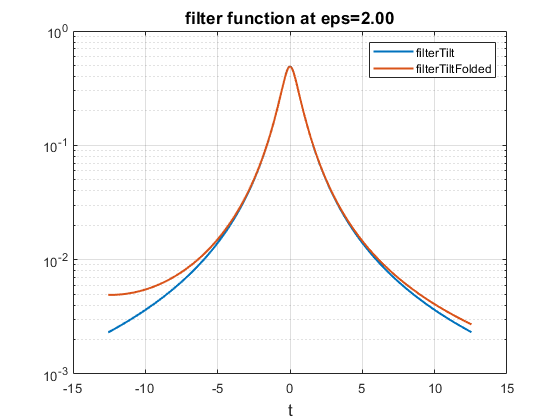

figure
semilogy(t_grid, abs(filterTilt_array),"LineWidth",1.5, "DisplayName","filterTilt");
hold on
semilogy(t_grid, abs(filterTiltFolded_array),"LineWidth",1.5,"DisplayName","filterTiltFolded");
xlabel("t",'FontSize',13);
title(sprintf("filter function at eps=%.2f", eps_test),'FontSize',13)
legend;
grid on;

% WARNING! This step is very time-consuming.

eps_grid = linspace(0.1,5,10);

% when we compute the E-gamma = int_R{p(x)*ramp(1-exp(eps-x))}
% so we can also derive continous and discrete verisions.
E_gammaChebfun = @(eps) sum(chebfun(@(x) f(x).*max(0,1-exp(eps-x)),[0,xmax],'splitting','on'));
E_gammaDiscrete = @(eps) sum(step_size*ps.*max(0,1-exp(eps-x_grid)));


deltaCfDiscrete = @(eps) 1/2/pi*sum(T_step_size*conj(arrayfun(@(t) filterTiltChebfun(eps,t),t_grid)).*cfTiltDiscrete_array);
deltaCfFFT = @(eps) 1/2/pi*sum(T_step_size*conj(arrayfun(@(t) filterTiltChebfun(eps,t),t_grid)).*cfTiltFFT_array);

deltaEdgeworth = @(eps) 1/2/pi*sum(T_step_size*conj(arrayfun(@(t) filterTiltChebfun(eps,t),t_grid)).*cfTiltEdgeworth_array);




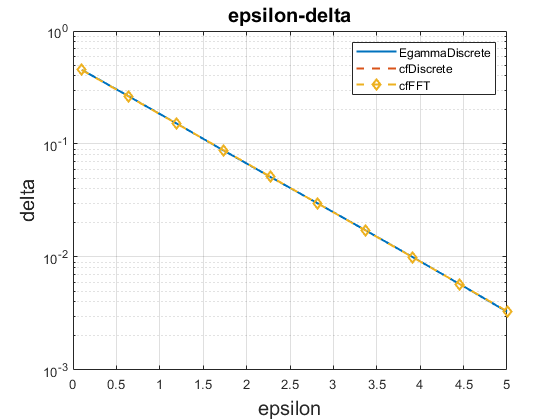

% take a look

figure

delta_EgammaDiscrete_array = arrayfun(E_gammaDiscrete,eps_grid);
semilogy(eps_grid,abs(delta_EgammaDiscrete_array),"LineWidth",1.5,"DisplayName","EgammaDiscrete");
hold on

% delta_EgammaChebfun_array = arrayfun(E_gammaChebfun,eps_grid);
% semilogy(eps_grid,abs(delta_EgammaChebfun_array),'--*',"LineWidth",1.5,"DisplayName","EgammaChebfun");
% hold on

delta_cfDiscrete_array = arrayfun(deltaCfDiscrete,eps_grid);
semilogy(eps_grid,abs(delta_cfDiscrete_array),'--',"LineWidth",1.5,"DisplayName","cfDiscrete");
hold on

% delta_cfEdgeworth = arrayfun(deltaEdgeworth,eps_grid);
% semilogy(eps_grid,abs(delta_cfEdgeworth),'--D',"LineWidth",1.5,"DisplayName","cfEdgeworth");
% hold on

delta_cfFFT_array = arrayfun(deltaCfFFT,eps_grid);
semilogy(eps_grid,abs(delta_cfFFT_array),'--D',"LineWidth",1.5,"DisplayName","cfFFT");
hold on

xlabel("epsilon","FontSize",15)
ylabel("delta","FontSize",15)
title("epsilon-delta","FontSize",15)
legend
grid on